# Pho Test Playground

**Pho Hale - Created 3-13-2020**

% mfilename('fullpath')
path = matlab.desktop.editor.getActiveFilename
% doc = matlab.desktop.editor.getActive
% doc = matlab.desktop.editor.findOpenDocument
% editor.Document
% doc.Filename
mfilename
directory_content = dir % contains everything of the current directory
exe_path = directory_content(1).folder % returns the path that is currently open

fprintf('%s\n',path)


videoFrameGateRect = [319.913260485224 9.09676368265632 17.174890796144 15.3794414144288];
curr_files_path = '..\Peekay_200116_143440';
curr_video_name = 'Peekay_20200116_143605803.avi';
curr_video_path = fullfile("..\Peekay_200116_143440\Peekay_20200116_143605803.avi");

test_path = genpath(curr_video_path);

[filepath,name,ext] = fileparts(curr_video_name)


## Testing of an Accumulator List

% 04-10-2020
% For each "kind" the user wants to store, create a list of field names to use
outVarNames = {'bad', 'comment'}

% A typeList is an array of frame numbers with an assigned name.

% User can:
% create a new typeList

% rename an existing typeList

% add or remove the current frame from a given typelist.

% see the typelists the current frame is a part of

% Optional: add/remove a range of frames from the typelist
% Optional: keep record of the last frame, so the user can specify "forward until now" to add a range of frames (inclusive or exclusive)

accumulator.('test') = {}

% curr_video_file.full_path = 'Z:\data\Lezio\LB_13\LB_13_190610\LB_13_190610_082833\EyePupil\PreSleep\video.avi';
% curr_video_file.full_parent_path = 'Z:\data\Lezio\LB_13\LB_13_190610\LB_13_190610_082833\EyePupil\PreSleep';
% curr_video_file.basename = 'video';

outputAbsoluteUniqueVideoIDString = GenerateAbsoluteVideoIdentifier(curr_video_file)

%"LB_13_190610_082833_EyePupil_PreSleep_video_44965"

[outputAbsoluteUniqueVideoIDString] = GenerateAbsoluteVideoIdentifier(curr_video_file)
testNumFrames = curr_video_file.endFrameIndex;
testVidId = outputAbsoluteUniqueVideoIDString;

% testNumFrames = 44965;
% testVidId = 'LB_13_190610_082833_EyePupil_PreSleep_video_44965';


uaMan = UserAnnotationsManager(outputAbsoluteUniqueVideoIDString, testNumFrames, 'Pho')

uaMan.addAnnotationType('BadPupilCenterOffset');
uaMan.addAnnotationType('BadPupilSize');
uaMan.addAnnotationType('BadEyePolyShape');
uaMan.addAnnotationType('BadUnspecified');

uaMan.addAnnotationType('UnusualFrame');
uaMan.addAnnotationType('EventChange');
uaMan.addAnnotationType('NeedsReview');

uaMan.UserAnnotationArrayNames
uaMan

uaMan.createAnnotation('NeedsReview', 22, 'test comment')
uaMan.getAnnotationsArray('NeedsReview')
uaMan

flattenedAnnotations = uaMan.flattenAnnotationsToFrames();
flattenedAnnotations
% jsonencode(uaMan)
json=savejson(flattenedAnnotations)
prettyjson(json)

uaMan = UserAnnotationsManager.loadFromExistingBackingFile()
uaMan

## Testing Diffing

listA = {'02','04','06','09','14','15','16'};
listB = {'02','04','06','09','12','14','15'};

% listA_Only = {'16'}
% bothLists = {'02','04','06','09','14','15'}
% listB_Only = {'12'}

listA_Only = {};
bothLists = {};
listB_Only = {};

% phoDiffOutput.listA

for i = 1:length(listA)
    was_found = false;
    for j = 1:length(listB)
        if strcmpi(listA{i}, listB{j})
            % If the item is found in both, add it to the common, and skip to the next item
            bothLists{end+1} = listA{i};
            was_found = true;
            break;
        end
    end % End inner for loop over listB items
    if ~was_found
        % If the item wasn't found in listB, it's listA exclusive
        listA_Only{end + 1} = listA{i};
    else
        % Remove the found item from listB to reduce the search time:
        listB(j) = [];
    end
end

% When all done, the listB_Only items are those that haven't been removed
listB_Only = listB;

listA_Only
bothLists
listB_Only




## Test Merging Implementation:

listA = {'02','04','06','09','14','15','16'};
listB = {'02','04','06','09','12','14','15'};

merged_list = [listA, listB]

merged_list = 1×14 cell array
    {'02'}    {'04'}    {'06'}    {'09'}    {'14'}    {'15'}    {'16'}    {'02'}    {'04'}    {'06'}    {'09'}    {'12'}    {'14'}    {'15'}


unique(merged_list)

ans = 1×8 cell array
    {'02'}    {'04'}    {'06'}    {'09'}    {'12'}    {'14'}    {'15'}    {'16'}


## Testing manipulation of external figures from live script

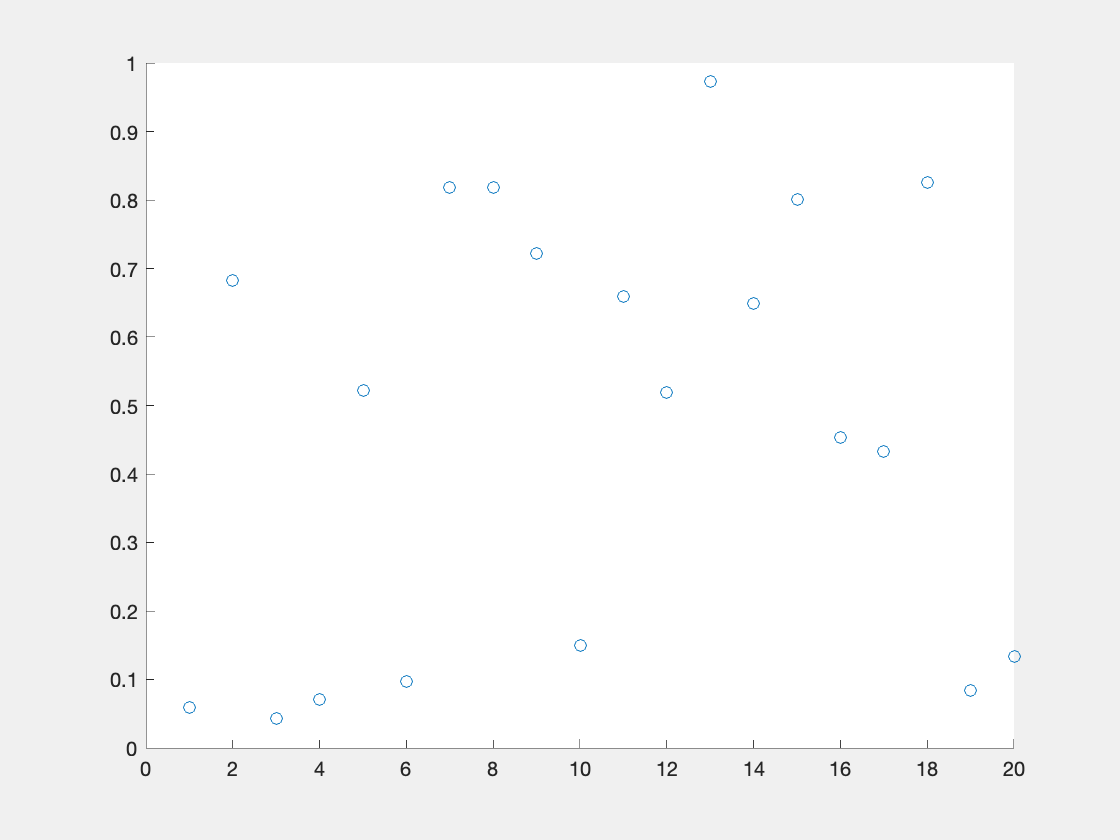

figure_index = 1337;
fig = figure(figure_index);
set(fig, 'Name','Measured Data','NumberTitle','off','Visible','on')
scatter((1:20),rand(1,20));

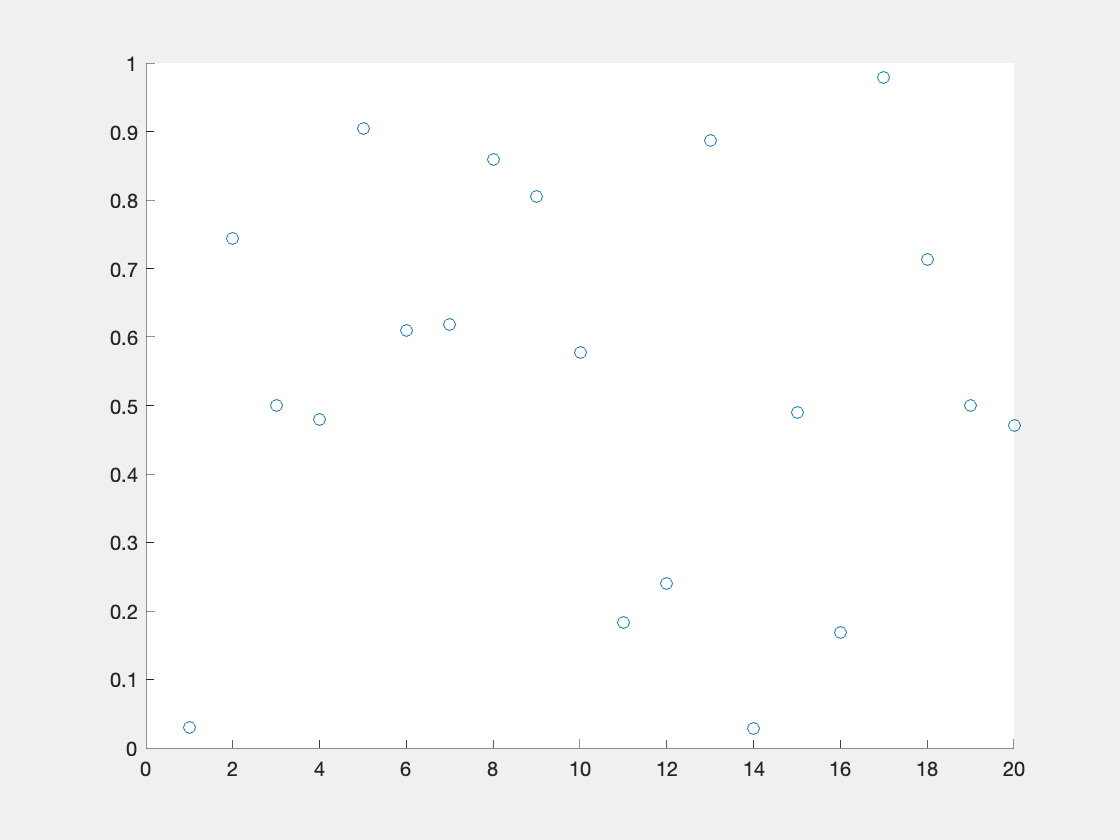

fig = figure(figure_index);
set(gcf,'Visible','on')
set(fig, 'Name','Measured Data Modified')

## Testing Updated (7-22-2020) Nanosecond-format filename parsing:

fileName = 'BehavioralBox_B00_T132399019137882781.mkv';
filename2 = 'BehavioralBox_B00_T132399019077675195.mkv';


length(fileName)
[videoFile] = ParsePhoOBSVideoFileName(fileName)

[videoFile2] = ParsePhoOBSVideoFileName(filename2)